# Summary of Alpha Values from VBWIM

% Search through VBResults and gather all 'All' alpha values! Scatter plot
clear, clc%, close all

D = linspecer(30);  
load('VBResultsNEW.mat')
VBR = VBResults.Weekly;

St = [2 4 6 8 10 15 20 25 30 40 50 60 70 80];
Lab = {'2', '4', '6', '8', '10', '15', '20', '25', '30', '40', '50', '60', '70', '80'};
Fi = [1 2 3 4 5  6  7  8  9  10 11 12 13 14];

[~, idx] = ismember(VBR.Span,St);
xdataTr = Fi(idx);
[~, idx] = ismember(VBResults.SS.Weekly.Span,St);
xdataTrSS = Fi(idx);

## Main Plot

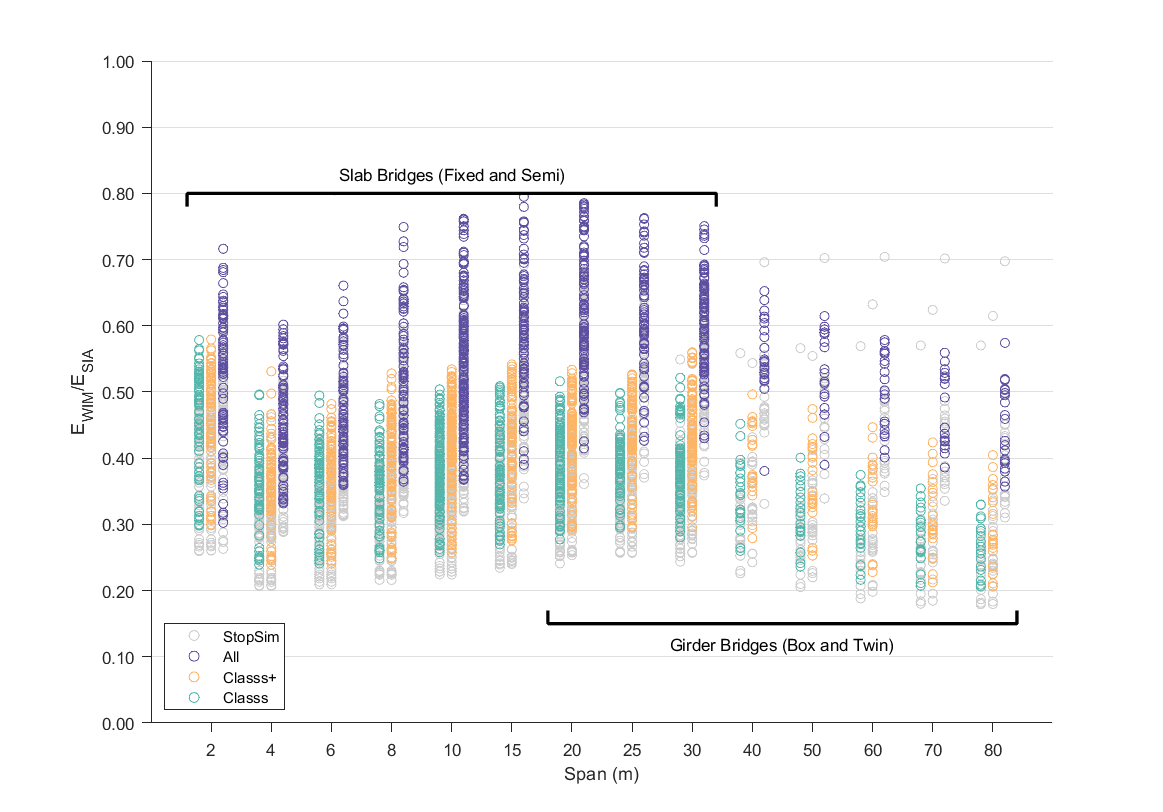

figure('Position',[325 225 930 650]); hold on;
scatter(xdataTrSS+0.2,VBResults.SS.Weekly.All./1.15,30,[0.8 0.8 0.8],'DisplayName','StopSim');
scatter(xdataTrSS,VBResults.SS.Weekly.ClassOW./1.15,30,[0.8 0.8 0.8],'HandleVisibility','off');
scatter(xdataTrSS-0.2,VBResults.SS.Weekly.Class./1.15,30,[0.8 0.8 0.8],'HandleVisibility','off');

scatter(xdataTr+0.2,VBR.All,30,D(1,:),'DisplayName','All');
scatter(xdataTr,VBR.ClassOW,30,D(21,:),'DisplayName','Class+');
scatter(xdataTr-0.2,VBR.Class,30,D(6,:),'DisplayName','Class');
xlim([0 max(Fi) + 1]); ylim([0 1])

ytickformat('%.2f'); yticks(0:0.1:1); set(gca,'TickDir','out');
set(gca,'YGrid','on');
xticks(Fi);
xticklabels(Lab);
xlabel('Span (m)')
%title('Weekly Block Maxima Summary')
ylabel('E_{WIM}/E_{SIA}')
legend('location','southwest')

yh = 0.8;
line([0.6,0.6,9.4,9.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
text(5,yh+0.03,'Slab Bridges (Fixed and Semi)','HorizontalAlignment','center')
yh = 0.15;
line([6.6,6.6,14.4,14.4],[yh+0.02,yh,yh,yh+0.02],'Color','k','LineWidth',2,'HandleVisibility','off')
text(10.5,yh-0.03,'Girder Bridges (Box and Twin)','HorizontalAlignment','center')

## Selectable Plot

% Refine VBR Based on checkboxes
LBox = VBR.Type == 'Box';
LTwin = VBR.Type == 'Twin';
LSlab = VBR.Type == 'Slab';

LMp = VBR.AE == 'Mp';
LMn = VBR.AE == 'Mn';
LV = VBR.AE == 'V';
LMxEdg = VBR.AE == 'MxEdg';
LMxMid = VBR.AE == 'MxMid';

Lp0 = VBR.Trans == 'p0';
Lp1 = VBR.Trans == 'p1';
Lp2 = VBR.Trans == 'p2';
Lp3 = VBR.Trans == 'p3';

LUni2L = VBR.Traffic == 'Uni2L';
LBi2L = VBR.Traffic == 'Bi2L';
LBi4L = VBR.Traffic == 'Bi4L';

### Type

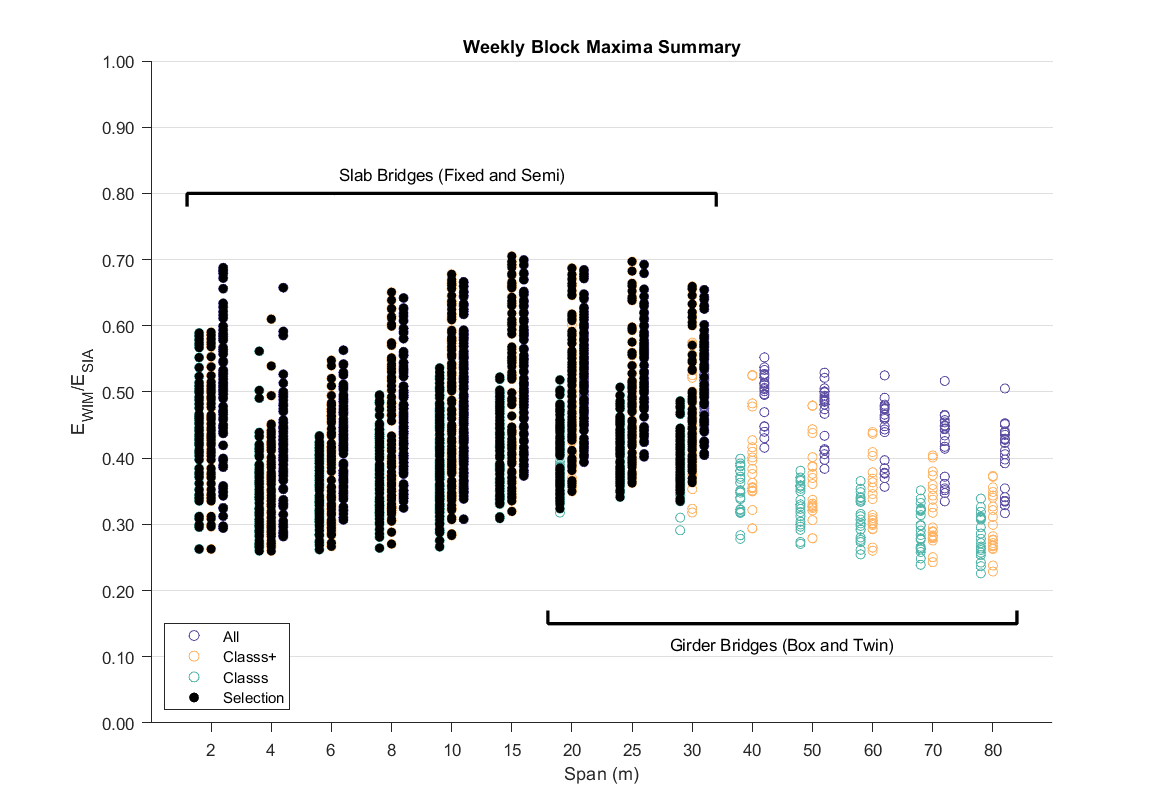

Box = false;
Twin = false;
Slab = true;

% Update logical
Log = any([Box*LBox Twin*LTwin Slab*LSlab],2);
% Combine Logicals to get master logical
xd = xdataTr(Log) + 0.2;
VBRPlot = VBR.All(Log);
try delete(h1); end
h1 = scatter(xd,VBRPlot,30,'k','filled','DisplayName','Selection');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Action Effect

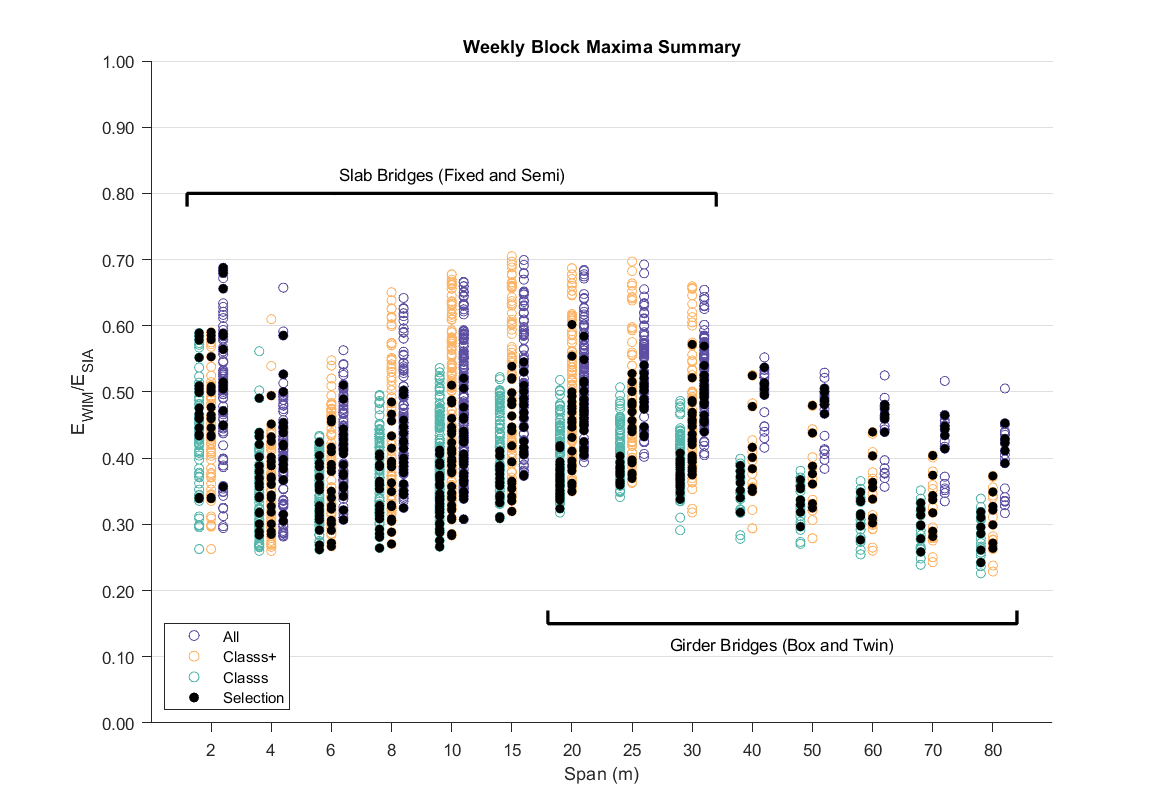

Mn = false;
Mp = true;
V = false;
MxEdg = false;
MxMid = false;

% Update logical
Log = any([Mn*LMn Mp*LMp V*LV MxEdg*LMxEdg MxMid*LMxMid],2);
% Combine Logicals to get master logical
xd = xdataTr(Log) + 0.2;
VBRPlot = VBR.All(Log);
try delete(h1); end
h1 = scatter(xd,VBRPlot,30,'k','filled','DisplayName','Selection');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Transverse Location

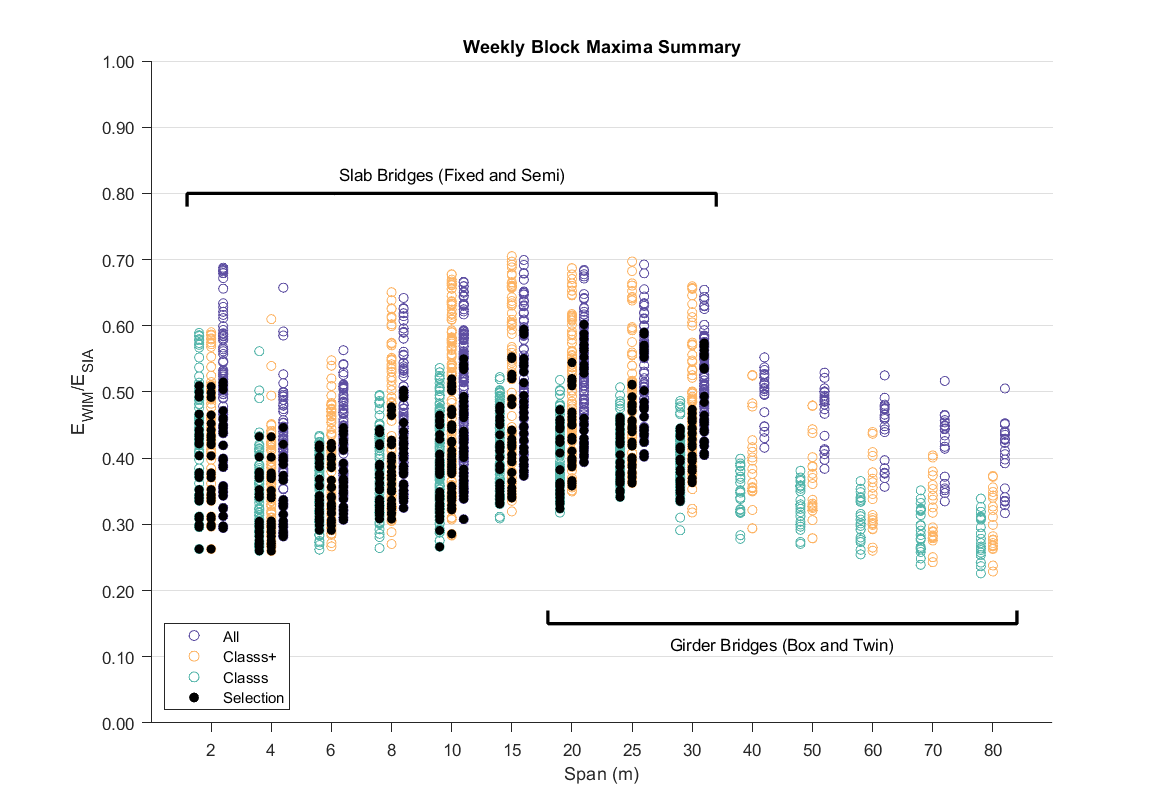

p0 = false;
p1 = false;
p2 = false;
p3 = true;

% Update logical
Log = any([p0*Lp0 p1*Lp1 p2*Lp2 p3*Lp3],2);
% Combine Logicals to get master logical
xd = xdataTr(Log) + 0.2;
VBRPlot = VBR.All(Log);
try delete(h1); end
h1 = scatter(xd,VBRPlot,30,'k','filled','DisplayName','Selection');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Transverse Location

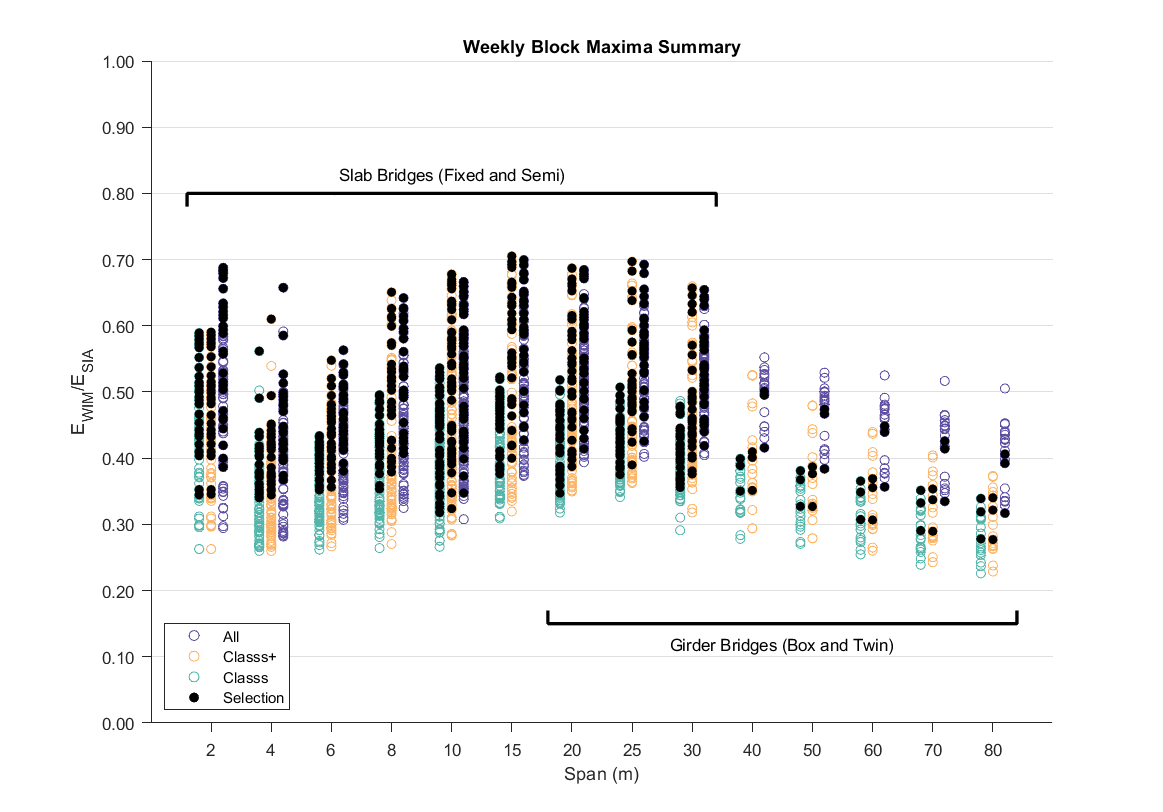

Uni2L = false;
Bi2L = false;
Bi4L = true;

% Update logical
Log = any([Uni2L*LUni2L Bi2L*LBi2L Bi4L*LBi4L],2);
% Combine Logicals to get master logical
xd = xdataTr(Log) + 0.2;
VBRPlot = VBR.All(Log);
try delete(h1); end
h1 = scatter(xd,VBRPlot,30,'k','filled','DisplayName','Selection');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');